# **第六章 决策树与随机森林**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **6.1 决策树简介**

        决策树是一种常用的机器学习算法，用于分类和回归任务。它的基本思想是将一个复杂的决策分解成一系列简单的决策，从而形成一个树状结构。决策树模拟了人类决策过程中的决策流程。它通过一系列的问题（决策节点），将数据集逐步分解为较小的子集。每个内部节点代表一个问题或一个属性的测试，每个分支代表测试的一个结果，而每个叶节点（树的末端）代表一个类别或者一个具体的预测结果。

        如图1所示，决策树就是一个类似流程图的树形结构，采用**自顶向下的递归方式**，从树的根节点开始，在它的内部节点上进行属性值的测试比较，然后按照给定实例的属性值确定对应的分支，最后在决策树的叶子节点得到结论。这个过程在**以新的节点为根的子树上重复**。

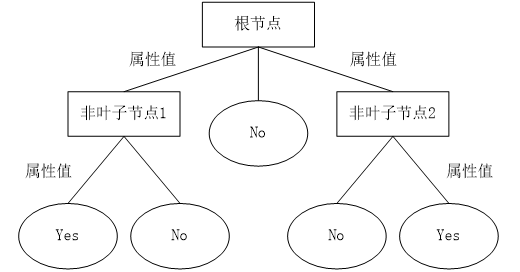

图1 决策树的拓扑结构图

        到目前为止，已经有多种决策树生成算法，但最有影响力的首推J.R.Quinlan的ID3算法，其开创性地引入了信息论中互信息的概念，并将其称为信息增益，以之作为属性选择的标准。为了精确地定义信息增益，我们先定义信息论中广泛使用地一个度量标准，称为熵（entropy），它定量刻画了随机变量的不确定性。

        如果目标属性有C个不同的值，那么对应的熵定义为：

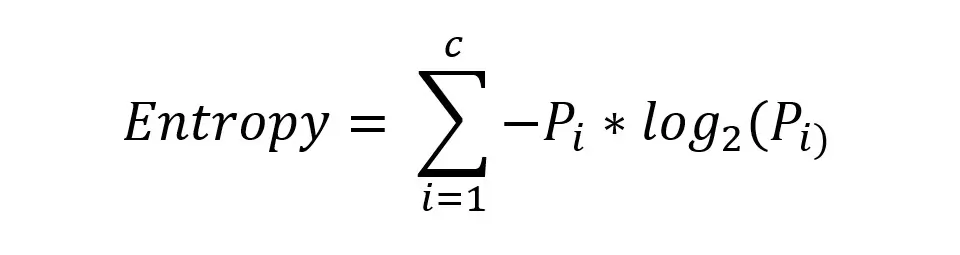

        随机变量发生概率与熵之间的关系如图2所示。若概率为0或1，则表明这是一个确定性的事件，对应的熵值为0；若两类发生的概率相等，则对应的熵值达到最大值，即熵值为1。

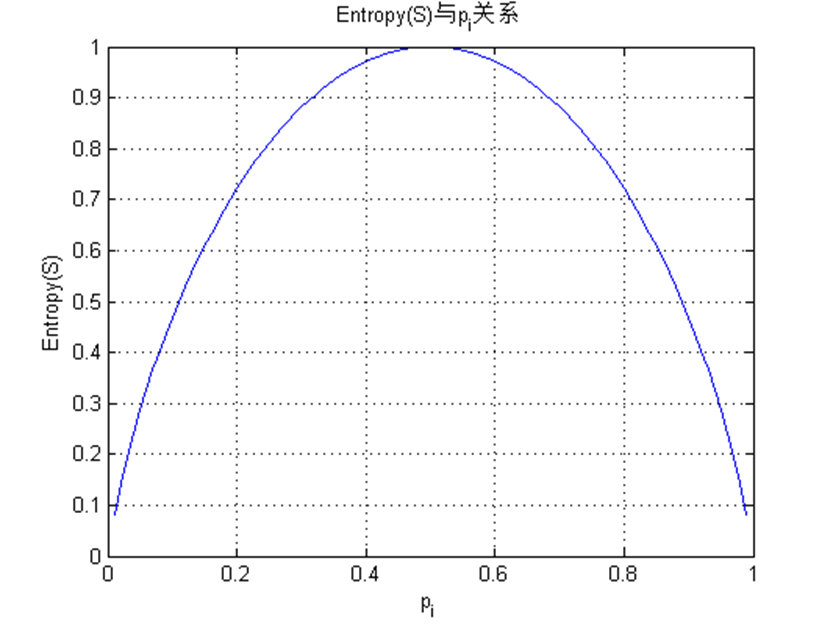

图2 随机变量发生概率与熵之间的关系

        借助熵的概念，信息增益的定义如下：

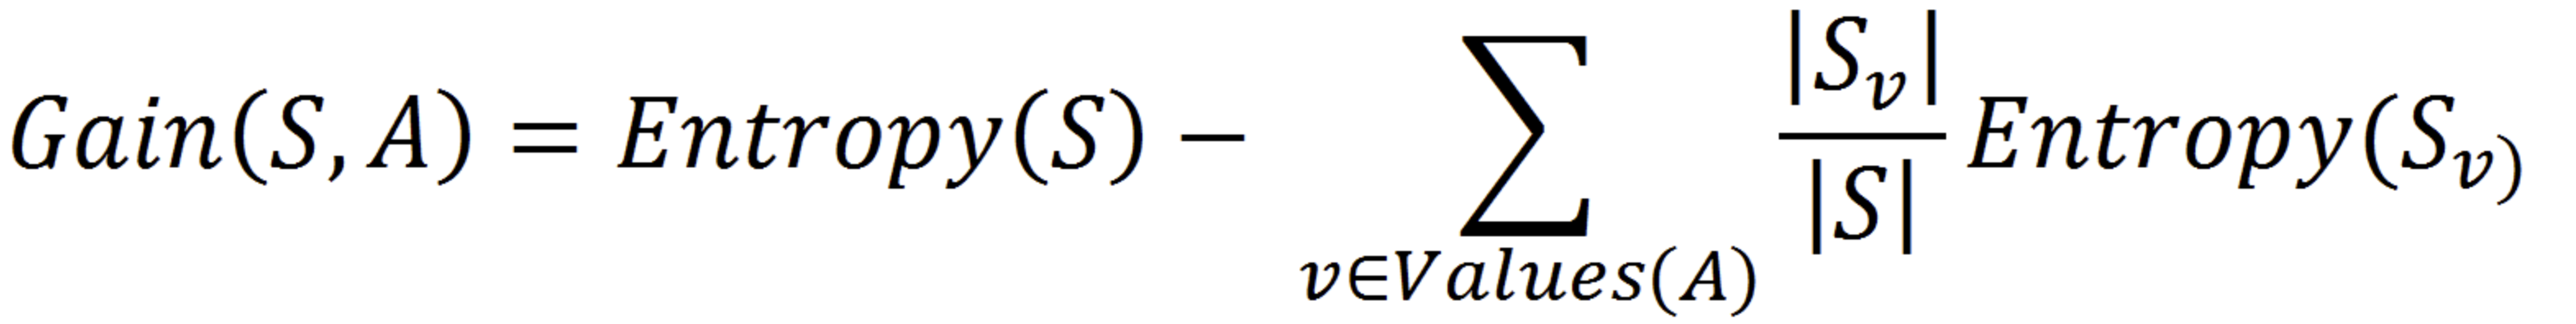

        信息增益主要用于衡量通过某个属性对数据集进行分割后所带来的“不确定性”的衰减。信息增益越高，意味着使用该属性进行分割后，得到的子集的不确定性衰减得越多，即使用该属性后，数据集由原来的很不确定变为很确定，该属性是一个区分度较好的属性，在构建决策树模型的过程中应优先考察该属性。  

        **ID3算法利用信息增益选择属性，但容易倾向于优先选择取值比较多的属性**。为了改进这个问题，C4.5算法应运而生，其主要改进的地方如下：

- **用信息增益率来选择属性。**信息增益率的定义如下：

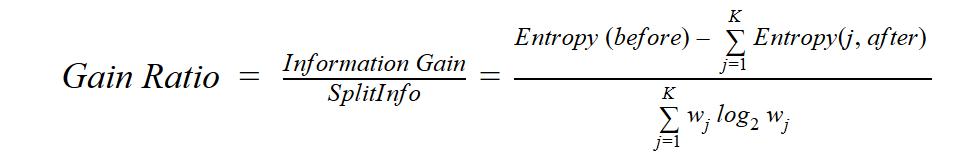

- **树的剪枝。**剪枝方法是用来处理过拟合问题而提出的。剪枝一般分两种方法：**先剪枝和后剪枝**。先剪枝方法通过提前停止树的构造，比如决定在某个节点不再分裂，而对树进行剪枝。一旦停止，该节点就变为叶子节点，该叶子节点可以取它所包含的子集中类别最多的类作为节点的类别。后剪枝的基本思路是对完全生长的树进行剪枝，通过删除节点的分支，并用叶子节点进行替换，叶子节点一般用子集中最频繁的类别进行标记。**C4.5算法采用悲观剪枝法，属于后剪枝方法的一种**，它的基本思路是：若使用叶子节点代替原来的子树后，误差率能够下降，则就用该叶子节点代替原来的子树。

        综上，决策树模型具有下列优点：

- **决策树易于理解和实现。 **人们在通过解释后都有能力去理解决策树所表达的意义。 

- **对于决策树，数据的准备往往是简单或者是不必要的。**其他的技术往往要求先把数据归一化，比如去掉多余的 或者空白的属性。 

- **能够同时处理数据型和常规型属性。** 其他的技术往往要求数据属性的单一。 

- **是一个白盒模型。**如果给定一个观察的模型，那么根据所产生的决策树很容易推出相应的逻辑表达式。

        此外，决策树模型也存在下列缺点：

- **对于各类别样本数量不一致的数据，在决策树当中信息增益的结果偏向于那些具有更多数值的特征。 **

- **决策树内部节点的判别具有明确性，这种明确性可能会带来误导。**

## **6.2 随机森林简介**

        随机森林（Random Forests，RF）是一种集成学习算法，它通过构建多个决策树并结合它们的预测结果来提高整体的预测准确性。随机森林既可以用于分类任务也可以用于回归任务，它是目前最流行和有效的机器学习算法之一。

        随机森林的基本思想是将多个决策树的预测结果集成起来，以此来提高预测的准确性和稳定性。每棵树独立地对数据进行预测，最终的预测结果是通过投票（对于分类问题）或平均（对于回归问题）得出的。

        随机森林包括两个主要的随机过程：

-  **Bootstrap抽样：**如图3所示，从原始数据集中通过有放回抽样的方式，抽取多个与原始数据集大小相同的样本集，用于训练不同的决策树。

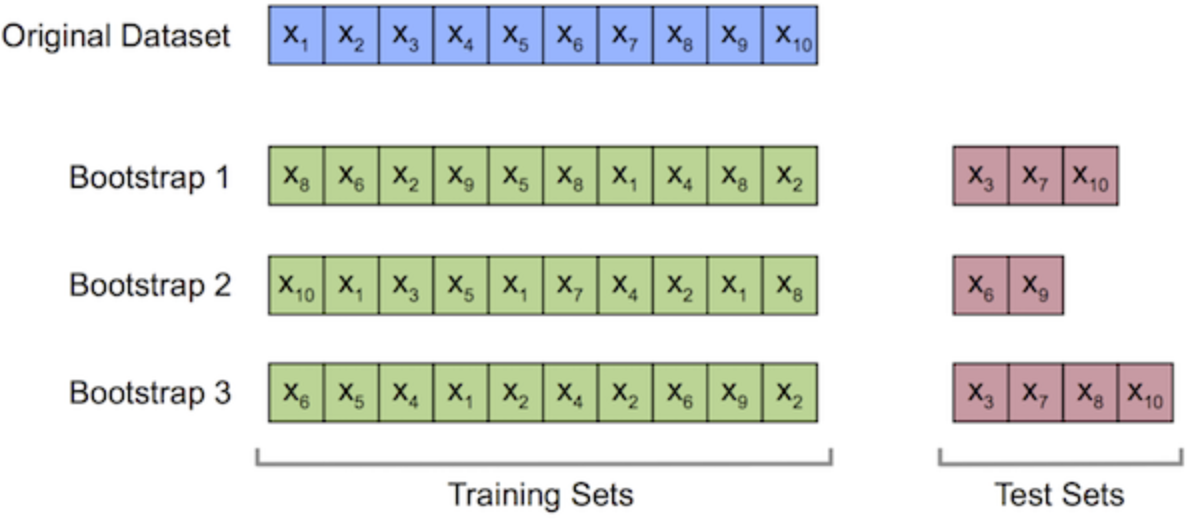

图3 Bootstrap抽样示意图

-  **随机选择特征：**如图4所示，在决策树的每个分裂节点，从所有特征中随机选择一部分特征，然后只在这些随机选择的特征中找到最佳分裂特征。

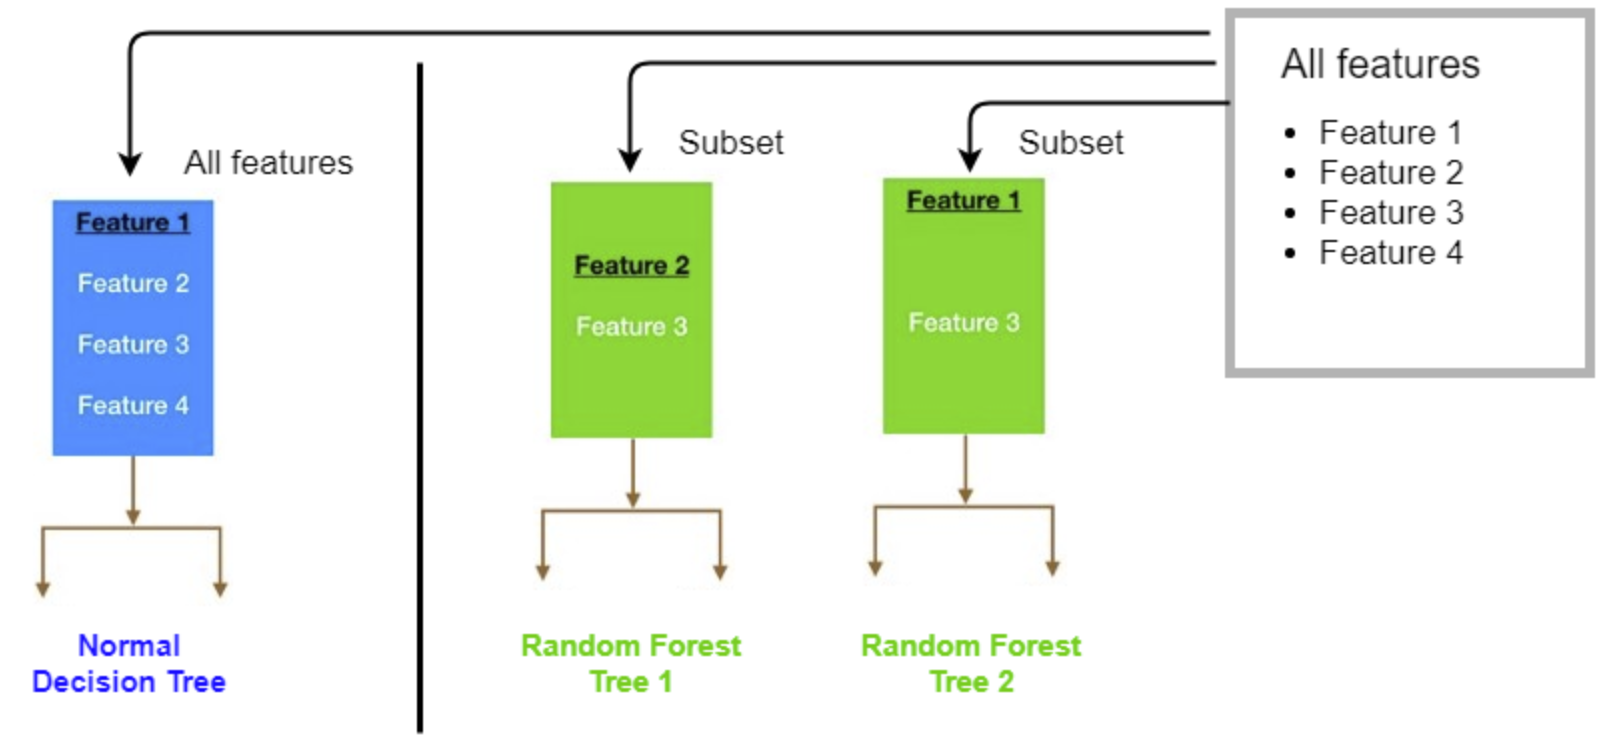

图4 随机选择特征示意图

        这两个随机过程确保了每棵树的独立性，从而降低了模型的方差，提高了泛化能力。

        如图5所示，当随机森林模型训练好后，对于测试集的样本，将其输入依次送入每一个决策树子模型，每个决策树子模型都会给出一个预测值Prediction 1，Prediction 2, ..., Prediction N，最后对上述预测值进行汇总即可，对于回归拟合问题而言，通常的做法是取平均值；对于分类识别问题而言，通常的做法是进行投票。

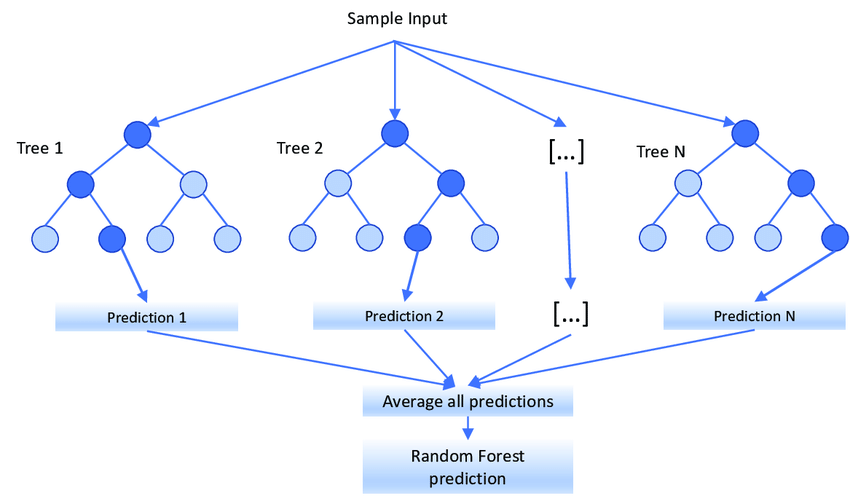

图5 随机森林模型预测过程示意图

## **6.3 案例1：基于决策树的乳腺癌肿瘤诊断**

- **数据集导入**

        数据文件data.mat文件中的变量data为569行32列的矩阵，每一行表示一个样本，第一列表示样本的ID，第二列表示样本的类别标签（1表示良性；2表示恶性），第3列至第32列表示样本的特征（属性）。

load data.mat

- ** 随机划分训练集/测试集**

        不失一般性，这里依然采用随机的方法产生训练集和测试集，即随机选取比例为k（0＜k＜1）的样本作为训练集，剩余的样本作为测试集用来对模型的性能进行评价。

% 1.随机产生训练集/测试集
n = size(data, 1);
a = randperm(n);
k = 0.9;
j = floor(n*k);
Train = data(a(1:j),:);
Test = data(a(j+1:end),:);

% 训练数据
P_train = Train(:,3:end);
T_train = Train(:,2);

% 测试数据
P_test = Test(:,3:end);
T_test = Test(:,2);

- **创建决策树分类器**

ctree = ClassificationTree.fit(P_train,T_train);

- **查看决策树模型    **

view(ctree);

Decision tree for classification
 1  if x28<0.14235 then node 2 elseif x28>=0.14235 then node 3 else 1
 2  if x21<16.805 then node 4 elseif x21>=16.805 then node 5 else 1
 3  if x3<71.815 then node 6 elseif x3>=71.815 then node 7 else 2
 4  if x11<1.04755 then node 8 elseif x11>=1.04755 then node 9 else 1
 5  if x2<16.375 then node 10 elseif x2>=16.375 then node 11 else 2
 6  class = 1
 7  if x14<13.93 then node 12 elseif x14>=13.93 then node 13 else 2
 8  class = 1
 9  class = 2
10  class = 1
11  if x9<0.15115 then node 14 elseif x9>=0.15115 then node 15 else 2
12  class = 1
13  if x7<0.062665 then node 16 elseif x7>=0.062665 then node 17 else 2
14  class = 1
15  if x12<1.8435 then node 18 elseif x12>=1.8435 then node 19 else 2
16  class = 1
17  if x5<0.079285 then node 20 elseif x5>=0.079285 then node 21 else 2
18  class = 2
19  class = 1
20  class = 1
21  class = 2



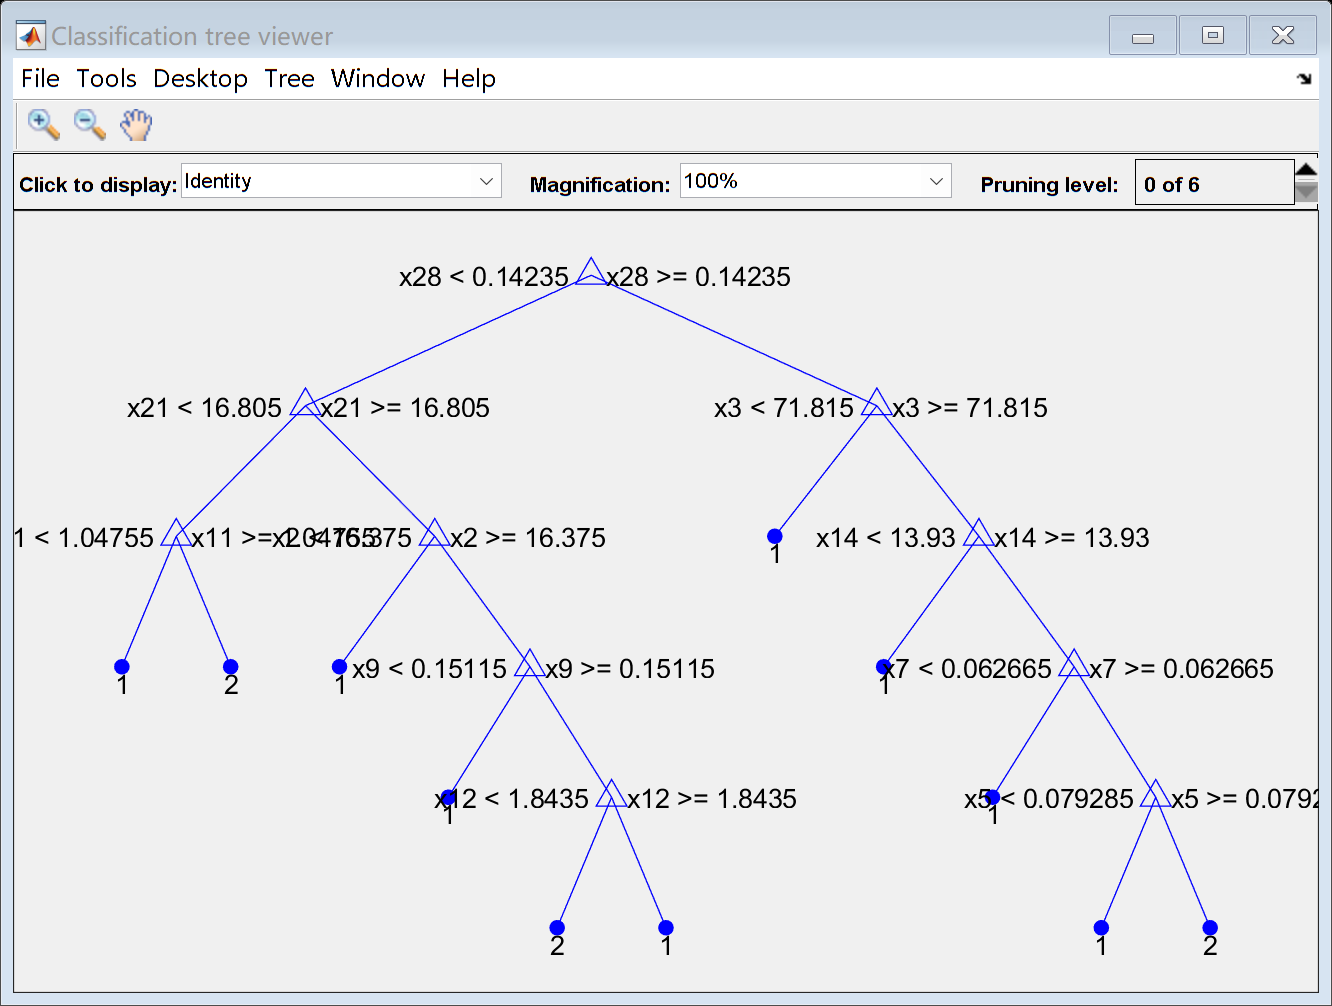

view(ctree,'Mode','graph');

- **决策树模型预测**

T_sim = predict(ctree,P_test);

- **结果分析**

count_B = length(find(T_train == 1));
count_M = length(find(T_train == 2));
rate_B = count_B / 500;
rate_M = count_M / 500;
total_B = length(find(data(:,2) == 1));
total_M = length(find(data(:,2) == 2));
number_B = length(find(T_sim == 1 & T_test == 1));
number_M = length(find(T_sim == 2 & T_test == 2));
number_B_sim = length(find(T_sim == 1 & T_test == 1));
number_M_sim = length(find(T_sim == 2 & T_test == 2));
disp(['病例总数：' num2str(569)...
      '  良性：' num2str(total_B)...
      '  恶性：' num2str(total_M)]);

病例总数：569  良性：357  恶性：212


disp(['训练集病例总数：' num2str(500)...
      '  良性：' num2str(count_B)...
      '  恶性：' num2str(count_M)]);

训练集病例总数：500  良性：325  恶性：187


disp(['测试集病例总数：' num2str(69)...
      '  良性：' num2str(number_B)...
      '  恶性：' num2str(number_M)]);

测试集病例总数：69  良性：29  恶性：20


disp(['良性乳腺肿瘤确诊：' num2str(number_B_sim)...
      '  误诊：' num2str(number_B - number_B_sim)...
      '  确诊率p1=' num2str(number_B_sim/number_B*100) '%']);

良性乳腺肿瘤确诊：29  误诊：0  确诊率p1=100%


disp(['恶性乳腺肿瘤确诊：' num2str(number_M_sim)...
      '  误诊：' num2str(number_M - number_M_sim)...
      '  确诊率p2=' num2str(number_M_sim/number_M*100) '%']);

恶性乳腺肿瘤确诊：20  误诊：0  确诊率p2=100%


## **6.4 案例2：基于随机森林模型的乳腺癌肿瘤诊断**

- **导入数据、训练集/测试集划分部分与案例1相同**

- **创建随机森林分类器**

model = classRF_train(P_train,T_train);

	Setting to defaults 500 trees and mtry=5



- **随机森林模型预测**

[T_sim,votes] = classRF_predict(P_test,model);

- **结果分析**

count_B = length(find(T_train == 1));
count_M = length(find(T_train == 2));
total_B = length(find(data(:,2) == 1));
total_M = length(find(data(:,2) == 2));
number_B = length(find(T_test == 1));
number_M = length(find(T_test == 2));
number_B_sim = length(find(T_sim == 1 & T_test == 1));
number_M_sim = length(find(T_sim == 2 & T_test == 2));
disp(['病例总数：' num2str(569)...
      '  良性：' num2str(total_B)...
      '  恶性：' num2str(total_M)]);
disp(['训练集病例总数：' num2str(500)...
      '  良性：' num2str(count_B)...

病例总数：569  良性：357  恶性：212


      '  恶性：' num2str(count_M)]);
disp(['测试集病例总数：' num2str(69)...
      '  良性：' num2str(number_B)...

训练集病例总数：500  良性：325  恶性：187


      '  恶性：' num2str(number_M)]);
disp(['良性乳腺肿瘤确诊：' num2str(number_B_sim)...
      '  误诊：' num2str(number_B - number_B_sim)...

测试集病例总数：69  良性：32  恶性：25


      '  确诊率p1=' num2str(number_B_sim/number_B*100) '%']);
disp(['恶性乳腺肿瘤确诊：' num2str(number_M_sim)...
      '  误诊：' num2str(number_M - number_M_sim)...

良性乳腺肿瘤确诊：32  误诊：0  确诊率p1=100%


      '  确诊率p2=' num2str(number_M_sim/number_M*100) '%']);

恶性乳腺肿瘤确诊：21  误诊：4  确诊率p2=84%


- **结果绘图**

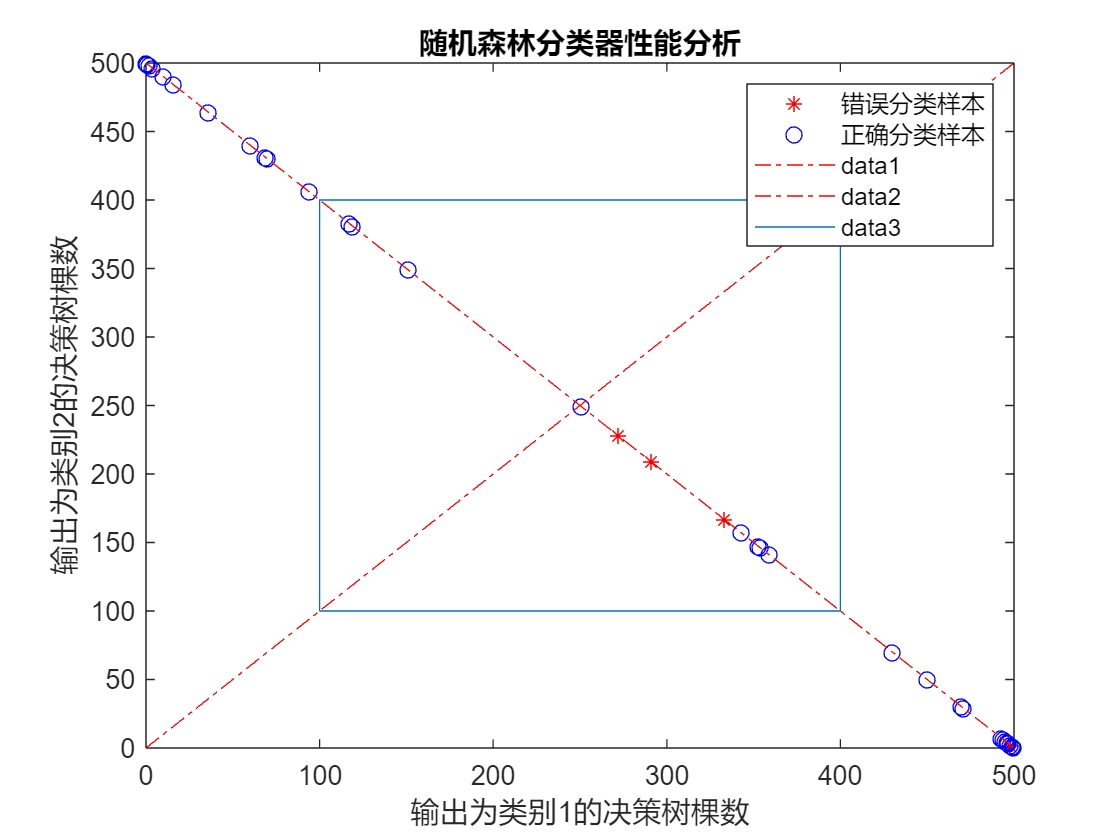

figure

index = find(T_sim ~= T_test);
plot(votes(index,1),votes(index,2),'r*')
hold on

index = find(T_sim == T_test);
plot(votes(index,1),votes(index,2),'bo')
hold on

legend('错误分类样本','正确分类样本')

plot(0:500,500:-1:0,'r-.')
hold on

plot(0:500,0:500,'r-.')
hold on

line([100 400 400 100 100],[100 100 400 400 100])

xlabel('输出为类别1的决策树棵数')
ylabel('输出为类别2的决策树棵数')

title('随机森林分类器性能分析')